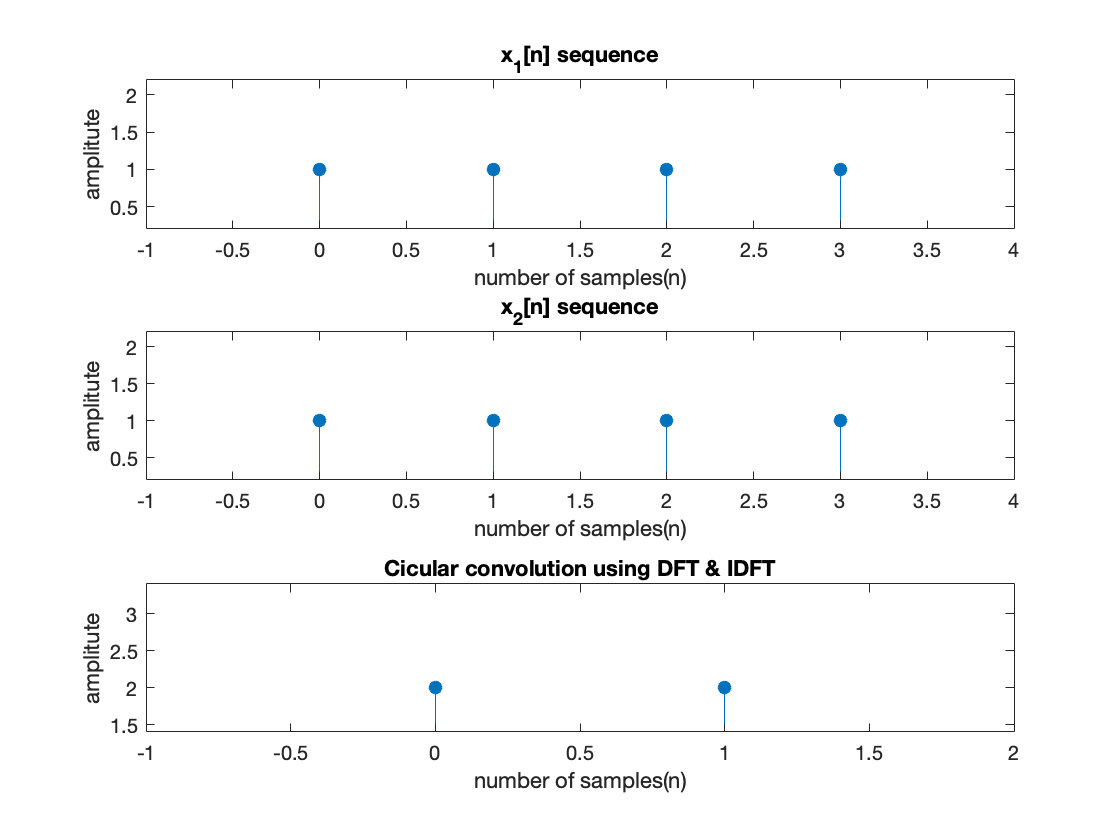

%----------------------------------------------------------------------
%Name : Sumit Patidar
%Roll no: B15237
%Task : program to compare linear and circular convolution
%----------------------------------------------------------------------

close all;
clear all;
clc;

%take sequence as an input 
%I am assuming sequence starts from n = 1
x1 = input('enter the sequence x1: '); %example input = [1 2 3 4 5]
x2 = input('enter the sequence x2: ');
x1_length = length(x1);
x2_length = length(x2);
n_length = x1_length + x2_length - 1; %the size of convoluted signal which we will get
n1 = 0:1:x1_length - 1;
n2 = 0:1:x2_length - 1;
n = 0:1:n_length - 1;

%plot sequence x1
p1 = subplot(3,1,1);
stem(n1, x1, 'filled');
xlabel('number of samples(n)');
ylabel('amplitute');
title('x_1[n] sequence');
hold on;

%plot sequence x2
p2 = subplot(3,1,2);
stem(n2, x2, 'filled');
xlabel('number of samples(n)');
ylabel('amplitute');
title('x_2[n] sequence');
hold on;

N = input('N points = ');
%get the dft of two sequences
X1 = dft_user(x1, N);
X2 = dft_user(x2, N);

%get the convolution
y = idft_user(X1.*X2, N);


%plot the circular convoluted sequence
p3 = subplot(3,1,3);
stem(0:N-1, abs(y), 'filled');
xlabel('number of samples(n)');
ylabel('amplitute');
title('Cicular convolution using DFT & IDFT');
hold on;


%setting axis limits to visualize better
axis(p1, [-1  x1_length min(abs(x1))*1.2-1 max(abs(x1))*1.2+1]);
axis(p2, [-1  x2_length min(abs(x2))*1.2-1 max(abs(x2))*1.2+1]);
axis(p3, [-1  N  min(abs(y))*1.2-1 max(abs(y))*1.2+1]);